# **Lab 4. Analysis of the optimal order**

Through this lab we will find the optimal order for a family of models, basing on the available data.

## 1. Defining the data generation mechanism

Before starting with our analysis, we need to define a data generation mechanism. In other words we have to define the system we want to identify in order to collect the vaues of its output in response to a given input. In this case we know what the real system is, but for our purposes we will extract a dataset and behave just like we do not know anything about it.

clc, clearvars, close all

### 1.1. Defining the system

We first define two vectors for the polynomials `A` and `B` of the ARX model.

% ARX polynomials
A = [1.00, -2.61,  2.49, -1.02, 0.15];
B = [0.00, -0.02, -0.03,  0.05, 0.01];

Then we choose the sampling time and the maximum number of data samples.

% Sampling time
Ts = 1;

% Number of samples
N = 500;

We use the `idpoly` function in order to declare a polynomial model with identifiable parameters, using the previously-defined polynomials. MATLAB will automatically recognize the ARX model and all of its parameters. We do not declare the variance of the noise directly into the command `idpoly` because we will introduce noise soon in a much more controlled way.

% System declaration
S = idpoly(A,B,[],[],[],0,Ts);

### 1.2. Extracting data from the system

We want to simulate the behaviour of the system given a random input vector in order to obtain the dataset to work with.

% Input vector
U  = randn(N,1);

% Output vector
Y = sim(S,U);

Finally we can declare our `iddata` object, which will be our starting dataset without uncertainty.

% Creating data object
data0 = iddata(Y,U,Ts);

### 1.3. Introducing noise in the system

Starting from the dataset without uncertainty, we define a noise vector using the command `filter`.

% Noise vector
v = filter(1, [1,-0.9], randn(N,1));

This vector will help us compute different noise vectors considering different magnitudes of the standard deviation.

% Noise vectors
v1 = v/std(v)*sqrt(0.001)*std(Y);
v2 = v/std(v)*sqrt(0.01)*std(Y);
v3 = v/std(v)*sqrt(0.1)*std(Y);
v4 = v/std(v)*sqrt(0.5)*std(Y);

We can extract different datasets by summing the noise vectors to the output vector.

% Outputs
Y1 = Y + v1;
Y2 = Y + v2;
Y3 = Y + v3;
Y4 = Y + v4;

### 1.4. Saving the datasets

We can declare different `iddata` objects, one for each of the new datasets.

% Creating data objects
data1 = iddata(Y1,U,Ts);
data2 = iddata(Y2,U,Ts);
data3 = iddata(Y3,U,Ts);
data4 = iddata(Y4,U,Ts);

Finally we save our data in the `dataset.mat` file using the command `save`.

% Saving data
save dataset.mat data0 data1 data2 data3 data4;

## 2. Digressing on the theory

There are several ways to study the optimal order of a family of models, depending on the size of the available data.

### 2.1. Adherence index

If the number of data samples is big enough to perform the split in training set and validation set, then it is possible to study the behaviour of the adherence index with respect to the order of the model. It is usally defined as the mean squared error:


$$J = \frac{1}{N} \sum_{i=1}^{N} \epsilon_i^2$$


and can be computed considering the prediction error or the simulation error.

### 2.2. Prediction error

The prediction error is defined as the difference between the real output and the predicted output from the model:


$$\epsilon_p(k) = y(k) - \hat{y}(k)$$


In order to assess the prediction error, we need to consider a block scheme like the following one:

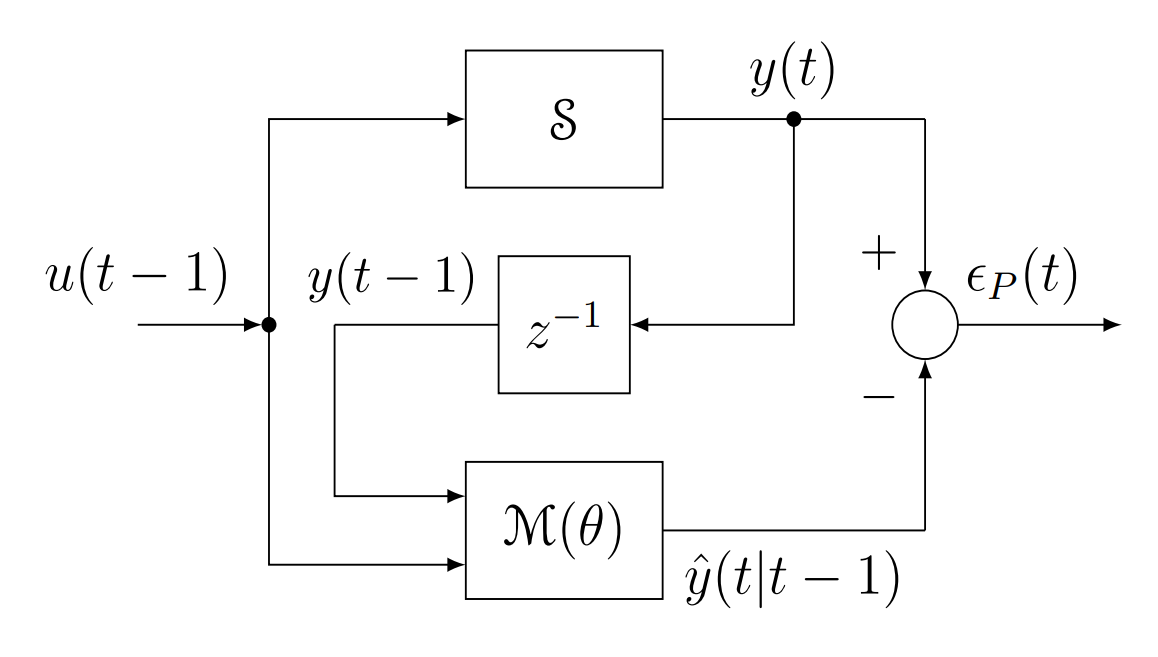

This means that our model will have as an input the so-called input $u\left(t-1\right)$ and the output of the system $y\left(t-1\right)$ delayed by one time sample. The output of the model will be subtracted to the output of the system in order to compute the prediction error $\epsilon_p \left(t\right)$.

Given the prediction error, the adherence index will be:


$$J = \frac{1}{N} \sum_{t=1}^{N} \epsilon_p^2(t)$$


### 2.3. Simulation error

The simulation error is defined as the difference between the real output and the simulated output from the model:


$$\epsilon_s(k) = y(k) - \widetilde{y}(k)$$


In order to assess the simulation error, we need to consider a block scheme like the following one:

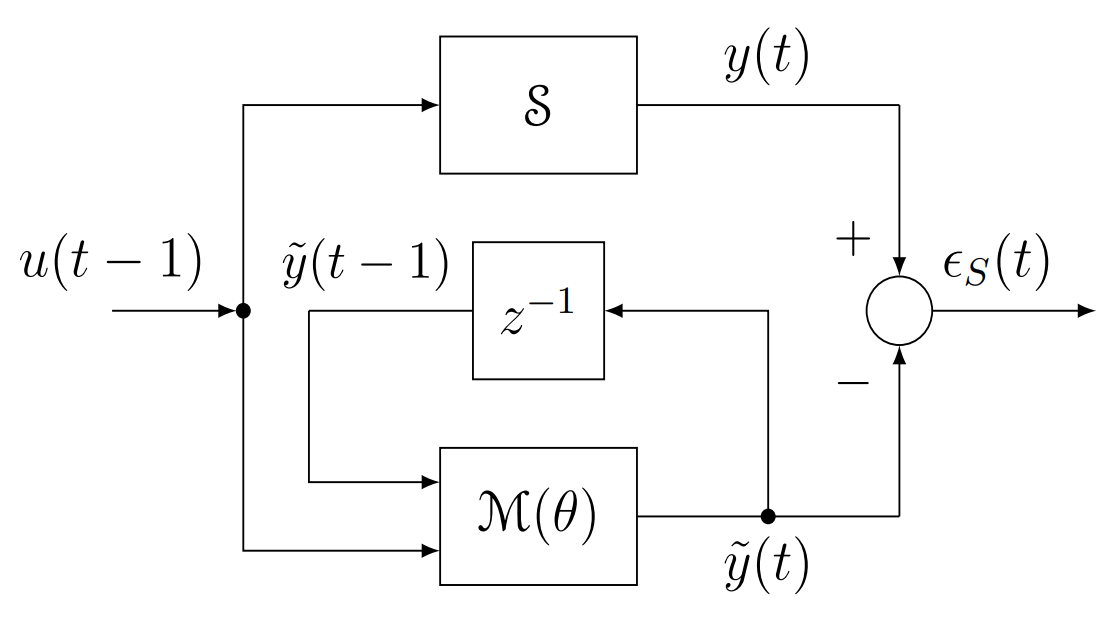

This means that our model will have as an input the so-called input $u\left(t-1\right)$ and the output of the model itself $\widetilde{y}(t-1)$ delayed by one time sample. In other words, the output of the system will not be considered as an input for the model because it is closed in a feedback loop. The output of the model will be subtracted to the output of the system in order to compute the simulation error $\epsilon_s \left(t\right)$.

Given the simulation error, the adherence index will be:


$$J = \frac{1}{N} \sum_{t=1}^{N} \epsilon_s^2(t)$$


### 2.4. Overtraining

We want our adherence index to be low. Depending on which output we are considering, the adherence index can be evaluated for the training set and for the validation set. If the output belongs to the training set we have the adherence index $J_t$ while if the output belongs to the validation set we have the adherence index $J_v \ldotp$ While the adherence index over the training set always decreases if we increase the order of the model, the adherence index over the validation set does not. This behaviour is known as overtraining.

Overtraining means that the model behaves perfectly on the training, because it memorized the training data, but behaves completely wrong on the validation because he is unable to generalize due to the fact that he had learned nothing.

### 2.5. Surrogate indexes

When data is not enough to perform the split in training and validation, in order to find the optimal order of the model, we need evaluate three surrogate indexes: Final Prediction Error, Akaike Information Criterion and Minimum Description Length.

The Final Prediction Error (FPE) is defined as:


$$\text{FPE} = \frac{N+n}{N-n}J_t$$


The Akaike Information Criterion (AIC) is defined as:


$$\text{AIC} = \log J_t+ \frac{2n}{N}$$


The Minimum Descritpion Length (MDL) is defined as:


$$\text{MDL} = \log J_t + \frac{n}{N}\log N$$


These indexes are always composed by a first term that decreases because of the adherence on the training set and a second term that penalizes the entire indexes as the order of the model increases. By summing the two contributes, the overall behaviour will show a first region in which the indexes decrease and a second region in which the indexes increase.

The optimal order of the model is the value of the order in which the index is minimum.

## 3. Finding the optimal order from the adherence index

Now that we have collected our data we can go on with the analysis of the optimal order with respect to the quadratic index.

clc, clearvars, close all

### 3.1. Loading data

Let's start by loading our datasets.

load dataset

We will now be able to find `data0`, `data1`, `data2`, `data3` and `data4` in the workspace.

### 3.2. Considering no uncertainty

Let's consider the first dataset `data0` which represents the case where there is no uncertainty in the system.

data = data0;

We use 300 samples out of the 500 total samples of the dataset for the training set, and the remaining others for the validation set.

% Split factor
Ns = 300;

% Number of samples
N = 500;

Since we want to assess the behaviour of the adherence index with respect to the order of the model chosen for identification, we will use a `for` loop to iterate over the possible values of the order. For this reason, we define a maximum order in order to stop the loop.

% Maximum order
nmax = 30;

for k=1:nmax

Once the loop has stated, we identify the system using an ARX model.

    % ARX(k,k,1) model
    m = arx(data(1:Ns),[k,k,1]);

Then we simulate the model in order to compute the simulated output. We also consider the real output.

    % Real output
    y = data.y;

    % Simulated output
    ys = sim(m,data.U);

In this way we can compute the simulation error as their difference. We also evaluate the prediction error using the command `pe`.

    % Simulation error
    es = y - ys;
    ep = pe(m,data).OutputData;

Given the prediction error and the simulation error, we can compute the adherence indexes over the training set and the validation set.

    % Adherence indexes based on the prediction error
    JPtrain(k) = cov(ep(1:Ns));
    JPvalid(k) = cov(ep(Ns+1:N));

    % Adherence indexes based on the simulation error
    JStrain(k) = cov(es(1:Ns));
    JSvalid(k) = cov(es(Ns+1:N));

end

To have some information about the identification in absence of uncertainty, we plot the prediction error.

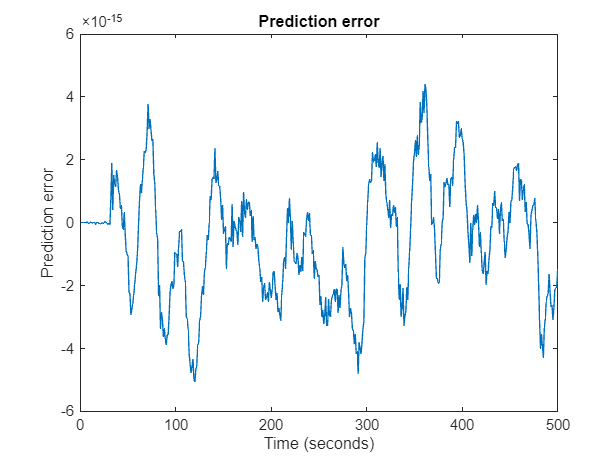

% Plotting prediction error
figure(1), plot(1:N,ep),
title("Prediction error"),
xlabel("Time (seconds)"),
ylabel("Prediction error")

As we can see it is very small, meaning the model behaved perfectly. Now we plot the adherence indexes.

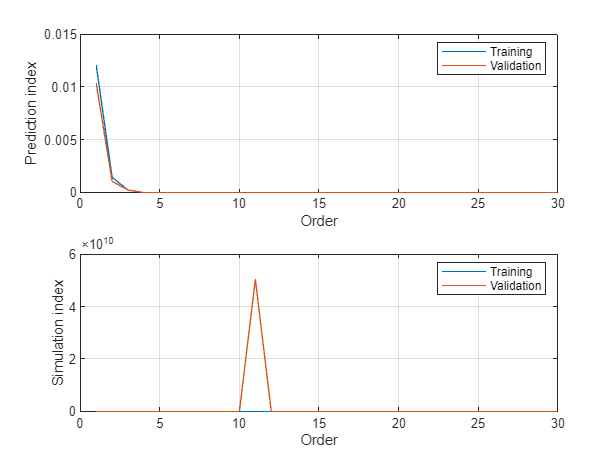

% Plotting adherence indexes
figure(2),

% Adherence indexes based on the prediction error
subplot(2,1,1), plot(1:nmax,JPtrain,1:nmax,JPvalid),
xlabel("Order"), ylabel("Prediction index"), grid,
legend("Training","Validation")

% Adherence indexes based on the simulation error
subplot(2,1,2), plot(1:nmax,JStrain,1:nmax,JSvalid),
xlabel("Order"), ylabel("Simulation index"), grid,
legend("Training","Validation")

We can see that there is a very discordant behaviour between the adherence indexes based on the prediction error and on the simulation error.  Other than that, we can see that in absence of uncertainty the adherence indexes computed over the training set and the validation set have more or less the same behaviour. Since the curves always decrease, the optimal order of the model is the minimum order at which the validation adherence index reaches its minimum value. 

Considering the prediction index, we have that the optimal order is:

% Optimal order
nopt = find(JPvalid == min(JPvalid))

nopt = 4

Let's see what score an ARX(7,7,1) model achieves.

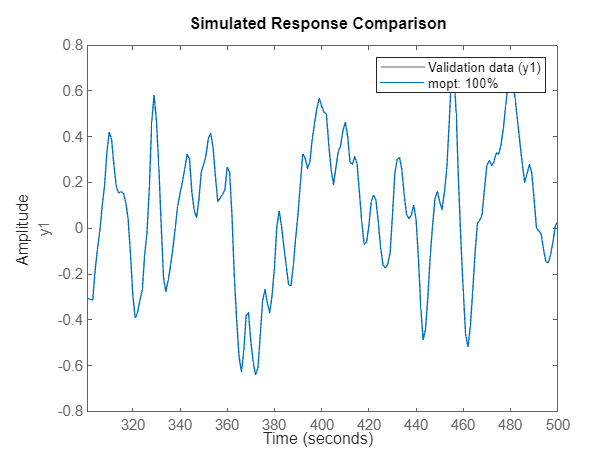

% Optimal model
mopt = arx(data(1:Ns),[nopt,nopt,1]);

% Evaluating model
figure(3), compare(data(Ns+1:N),mopt)

As we can see our model is perfect because its fit is 100%. Let's consider the simulation index:

% Optimal order
nopt = find(JSvalid == min(JSvalid))

nopt = 23

This optimal order is way bigger than the one found with the prediction index. Let's see what score an ARX(28,28,1) model achieves.

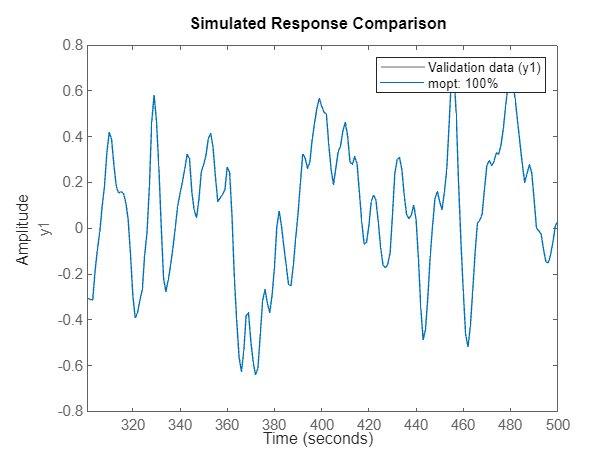

% Optimal model
mopt = arx(data(1:Ns),[nopt,nopt,1]);

% Evaluating model
figure(4), compare(data(Ns+1:N),mopt)

As we can see, also this model is perfect. In this case is much more convenient to consider 8 as the optimal order.

### 3.3. Considering light uncertainty

Let's now consider the dataset `data2` which represents the case where there is a light uncertainty in the system.

data = data2;

We use 300 samples out of the 500 total samples of the dataset for the training set, and the remaining others for the validation set.

% Split factor
Ns = 300;

% Number of samples
N = 500;

Since we want to assess the behaviour of the adherence index with respect to the order of the model chosen for identification, we will use a `for` loop to iterate over the possible values of the order. For this reason, we define a maximum order in order to stop the loop.

% Maximum order
nmax = 30;

for k=1:nmax

Once the loop has stated, we identify the system using an ARX model.

    % ARX(k,k,1) model
    m = arx(data(1:Ns),[k,k,1]);

Then we simulate the model in order to compute the simulated output. We also consider the real output.

    % Real output
    y = data.y;

    % Simulated output
    ys = sim(m,data.U);

In this way we can compute the simulation error as their difference. We also evaluate the prediction error using the command `pe`.

    % Simulation error
    es = y - ys;
    ep = pe(m,data).OutputData;

Given the prediction error and the simulation error, we can compute the adherence indexes over the training set and the validation set.

    % Adherence indexes based on the prediction error
    JPtrain(k) = cov(ep(1:Ns));
    JPvalid(k) = cov(ep(Ns+1:N));

    % Adherence indexes based on the simulation error
    JStrain(k) = cov(es(1:Ns));
    JSvalid(k) = cov(es(Ns+1:N));

end

To have some information about the identification in absence of uncertainty, we plot the prediction error.

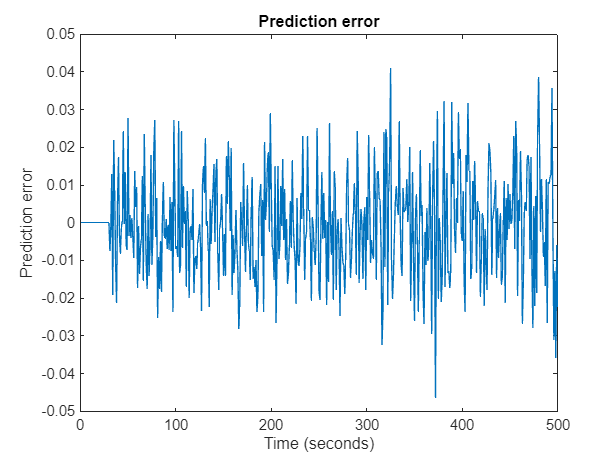

% Plotting prediction error
figure(5), plot(1:N,ep),
title("Prediction error"),
xlabel("Time (seconds)"),
ylabel("Prediction error")

As we can see it is small, but not neglectable, meaning the noise had some consequences on the behaviour of the model.

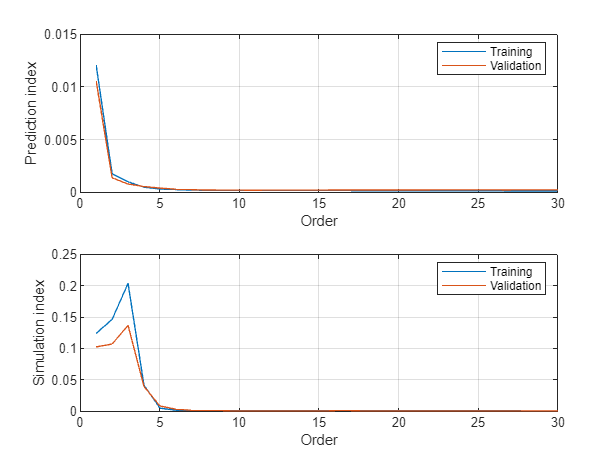

% Plotting adherence indexes
figure(6),

% Adherence indexes based on the prediction error
subplot(2,1,1), plot(1:nmax,JPtrain,1:nmax,JPvalid),
xlabel("Order"), ylabel("Prediction index"), grid,
legend("Training","Validation")

% Adherence indexes based on the simulation error
subplot(2,1,2), plot(1:nmax,JStrain,1:nmax,JSvalid),
xlabel("Order"), ylabel("Simulation index"), grid,
legend("Training","Validation")

We can see that there is still a very discordant behaviour between the adherence indexes based on the prediction error and on the simulation error. Other than that, we can see that in presence of light uncertainty the adherence indexes computed over the training set and the validation set have now a different behaviour. The adherence indexes computed over the training set always decrease, while the adherence indexes computed over the validation set tend to increase with respect to the order of the model. 

Considering the prediction index, we have that the optimal order is:

% Optimal order
nopt = find(JPvalid == min(JPvalid))

nopt = 11

Let's see what score an ARX(14,14,1) model achieves.

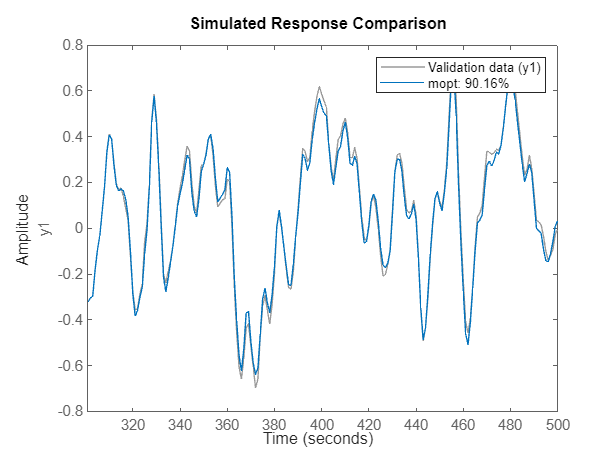

% Optimal model
mopt = arx(data(1:Ns),[nopt,nopt,1]);

% Evaluating model
figure(7), compare(data(Ns+1:N),mopt)

As we can see our model is quite perfect. Let's consider the simulation index:

% Optimal order
nopt = find(JSvalid == min(JSvalid))

nopt = 13

This optimal order is smaller than the one found with the prediction index. Let's see what score an ARX(8,8,1) model achieves.

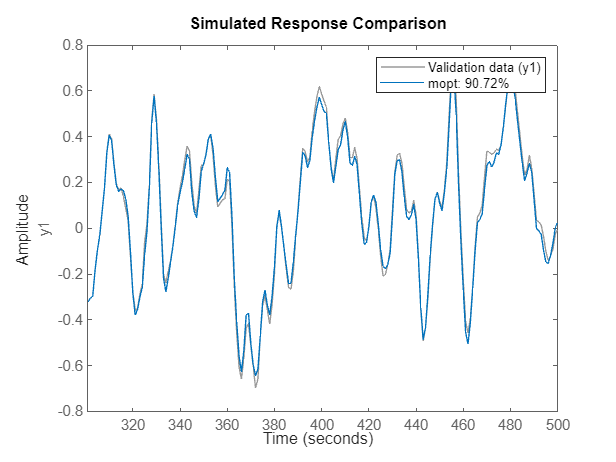

% Optimal model
mopt = arx(data(1:Ns),[nopt,nopt,1]);

% Evaluating model
figure(8), compare(data(Ns+1:N),mopt)

As we can see, this model is better than the previous one. This means that the adherence indexes based on the simulation error have been more helpful compared to the adherence indexes based on the prediction error.

### 3.4. Considering heavy uncertainty

Let's now consider the dataset `data4` which represents the case where there is a heavy uncertainty in the system.

data = data4;

We use 300 samples out of the 500 total samples of the dataset for the training set, and the remaining others for the validation set.

% Split factor
Ns = 300;

% Number of samples
N = 500;

Since we want to assess the behaviour of the adherence index with respect to the order of the model chosen for identification, we will use a `for` loop to iterate over the possible values of the order. For this reason, we define a maximum order in order to stop the loop.

% Maximum order
nmax = 30;

for k=1:nmax

Once the loop has stated, we identify the system using an ARX model.

    % ARX(k,k,1) model
    m = arx(data(1:Ns),[k,k,1]);

Then we simulate the model in order to compute the simulated output. We also consider the real output.

    % Real output
    y = data.y;

    % Simulated output
    ys = sim(m,data.U);

In this way we can compute the simulation error as their difference. We also evaluate the prediction error using the command `pe`.

    % Simulation error
    es = y - ys;
    ep = pe(m,data).OutputData;

Given the prediction error and the simulation error, we can compute the adherence indexes over the training set and the validation set.

    % Adherence indexes based on the prediction error
    JPtrain(k) = cov(ep(1:Ns));
    JPvalid(k) = cov(ep(Ns+1:N));

    % Adherence indexes based on the simulation error
    JStrain(k) = cov(es(1:Ns));
    JSvalid(k) = cov(es(Ns+1:N));

end

To have some information about the identification in absence of uncertainty, we plot the prediction error.

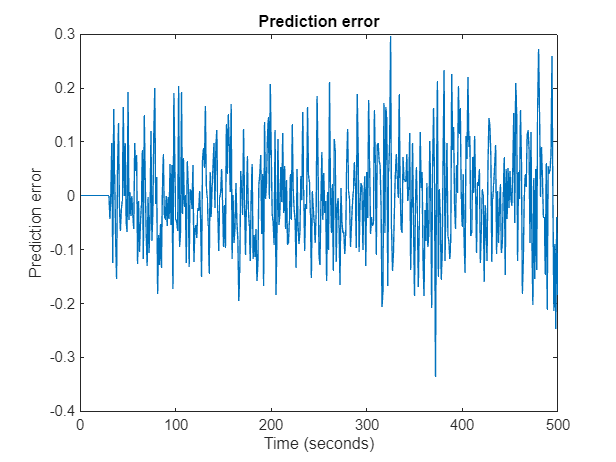

% Plotting prediction error
figure(9), plot(1:N,ep),
title("Prediction error"),
xlabel("Time (seconds)"),
ylabel("Prediction error")

As we can see it is small, but not neglectable, meaning the noise had some consequences on the behaviour of the model.

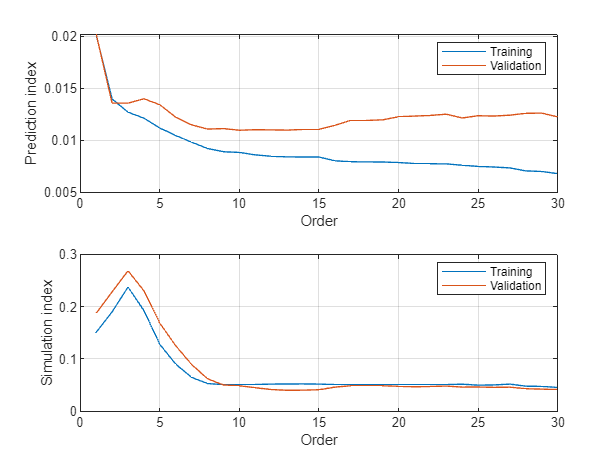

% Plotting adherence indexes
figure(10),

% Adherence indexes based on the prediction error
subplot(2,1,1), plot(1:nmax,JPtrain,1:nmax,JPvalid),
xlabel("Order"), ylabel("Prediction index"), grid,
legend("Training","Validation")

% Adherence indexes based on the simulation error
subplot(2,1,2), plot(1:nmax,JStrain,1:nmax,JSvalid),
xlabel("Order"), ylabel("Simulation index"), grid,
legend("Training","Validation")

We can see that there is still a very discordant behaviour between the adherence indexes based on the prediction error and on the simulation error. Other than that, we can see that in presence of heavy uncertainty the adherence indexes computed over the training set and the validation set have now a different behaviour. The adherence indexes computed over the training set always decrease, while the adherence indexes computed over the validation set tend to diverge with respect to the order of the model. 

Considering the prediction index, we have that the optimal order is:

% Optimal order
nopt = find(JPvalid == min(JPvalid))

nopt = 10

Let's see what score an ARX(13,13,1) model achieves.

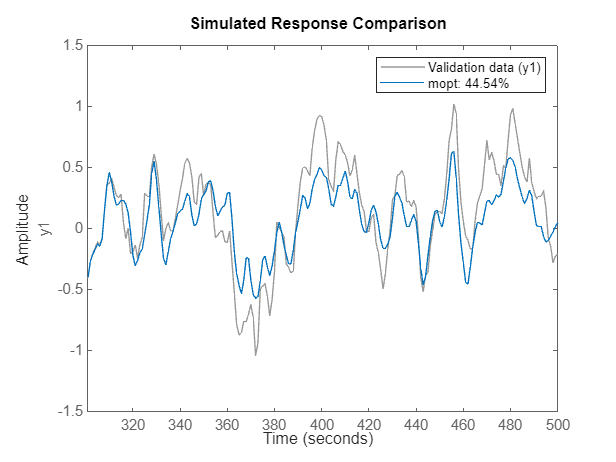

% Optimal model
mopt = arx(data(1:Ns),[nopt,nopt,1]);

% Evaluating model
figure(11), compare(data(Ns+1:N),mopt)

As we can see our model is not so good. Let's consider the simulation index:

% Optimal order
nopt = find(JSvalid == min(JSvalid))

nopt = 13

This optimal order is smaller than the one found with the prediction index. Let's see what score an ARX(8,8,1) model achieves.

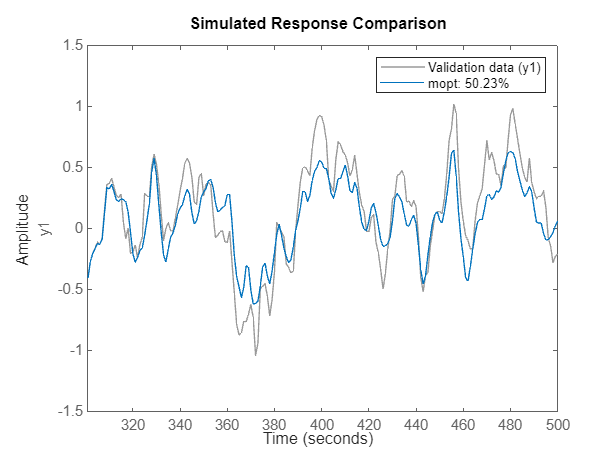

% Optimal model
mopt = arx(data(1:Ns),[nopt,nopt,1]);

% Evaluating model
figure(12), compare(data(Ns+1:N),mopt)

As we can see, this model is better than the previous one. This means that, even in this case, the adherence indexes based on the simulation error have been more helpful compared to the adherence indexes based on the prediction error.

## 4. Finding the optimal order using surrogate indexes

Let us now consider the case where we do not have enough data to perform the split in training set and validation set. In order to understand which is the optimal order of the model, we need to evaluate three surrogate indexes: the Final Prediction Error (FPE), the Akaike Information Criterion (AIC) and the Minimum Description Length (MDL).

clc, clearvars, close all

### 4.1. Loading data

Let's start by loading our datasets.

load dataset

We will now be able to find `data0`, `data1`, `data2`, `data3` and `data4` in the workspace.

### 4.2. Considering no uncertainty

Let's consider the first dataset `data0` which represents the case where there is no uncertainty in the system.

data = data0;

We now suppose that we only have 300 samples, so we cannot perform the split of the dataset.

% Number of samples
Ns = 300;

Since we want to assess the behaviour of the surrogate index with respect to the order of the model chosen for identification, we will use a `for` loop to iterate over the possible values of the order. For this reason, we define a maximum order in order to stop the loop.

% Maximum order
nmax = 30;

for k=1:nmax

Once the loop has stated, we identify the system using an ARX model.

    % ARX(k,k,1) model
    m = arx(data(1:Ns),[k,k,1]);

Then we simulate the model in order to compute the simulated output. We also consider the real output.

    % Real output
    y = data.y;

    % Simulated output
    ys = sim(m,data.U);

In this way we can compute the simulation error as their difference. We also evaluate the prediction error using the command `pe`.

    % Simulation error
    es = y - ys;
    ep = pe(m,data).OutputData;

Given the prediction error and the simulation error, we can compute the adherence indexes.

    % Adherence indexes based on the prediction error
    JP(k) = cov(ep(1:Ns));

    % Adherence indexes based on the simulation error
    JS(k) = cov(es(1:Ns));

Given the adherence indexes we can compute the surrogate indexes.

    % Final Prediction Error
    Jfpe(k) = fpe(m);

    % Akaike Information Criterion
    Jaic(k) = aic(m);

    % Minimum Description Length
    Jmdl(k) = log(Ns)*2*k/Ns + log(JP(k));

end

Now we can plot the surrogate indexes in order to evaluate them.

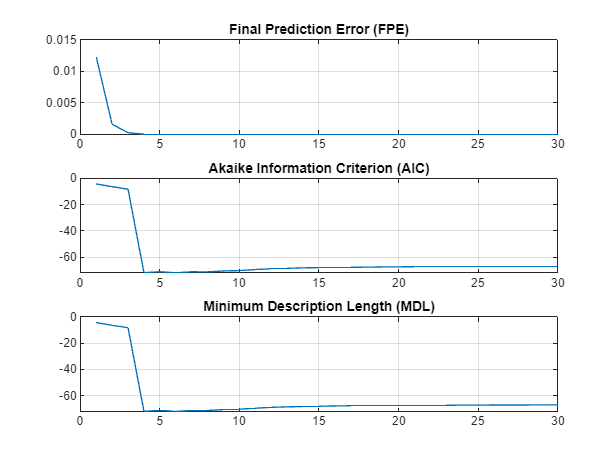

% Plotting surrogate indexes
figure(13),

% Final Prediction Error
subplot(3,1,1), plot(1:nmax,Jfpe),
title("Final Prediction Error (FPE)"), grid

% Akaike Information Criterion
subplot(3,1,2), plot(1:nmax,Jaic),
title("Akaike Information Criterion (AIC)"), grid

% Minimum Description Length
subplot(3,1,3), plot(1:nmax,Jmdl),
title("Minimum Description Length (MDL)"), grid;

As we can see they initially decrease when increasing the order of the model and then increase. This highlights the behaviour of these indexes to penalize very large values of the order of the model, at the point that they weight more than the adherence.

The Minimum Description Length (MDL) index is the most valuable index because it shows clearly which is the optimal order.

% Optimal order
nopt = find(Jmdl == min(Jmdl))

nopt = 6

This optimal order is equal to the one found with the adherence indexes, meaning that MDL is a good criterion.

### 4.3. Considering light uncertainty

Let's now consider the dataset `data2` which represents the case where there is a light uncertainty in the system.

data = data2;

We now suppose that we only have 300 samples, so we cannot perform the split of the dataset.

% Number of samples
Ns = 300;

Since we want to assess the behaviour of the surrogate index with respect to the order of the model chosen for identification, we will use a `for` loop to iterate over the possible values of the order. For this reason, we define a maximum order in order to stop the loop.

% Maximum order
nmax = 30;

for k=1:nmax

Once the loop has stated, we identify the system using an ARX model.

    % ARX(k,k,1) model
    m = arx(data(1:Ns),[k,k,1]);

Then we simulate the model in order to compute the simulated output. We also consider the real output.

    % Real output
    y = data.y;

    % Simulated output
    ys = sim(m,data.U);

In this way we can compute the simulation error as their difference. We also evaluate the prediction error using the command `pe`.

    % Simulation error
    es = y - ys;
    ep = pe(m,data).OutputData;

Given the prediction error and the simulation error, we can compute the adherence indexes.

    % Adherence indexes based on the prediction error
    JP(k) = cov(ep(1:Ns));

    % Adherence indexes based on the simulation error
    JS(k) = cov(es(1:Ns));

Given the adherence indexes we can compute the surrogate indexes.

    % Final Prediction Error
    Jfpe(k) = fpe(m);

    % Akaike Information Criterion
    Jaic(k) = aic(m);

    % Minimum Description Length
    Jmdl(k) = log(Ns)*2*k/Ns + log(JP(k));

end

Now we can plot the surrogate indexes in order to evaluate them.

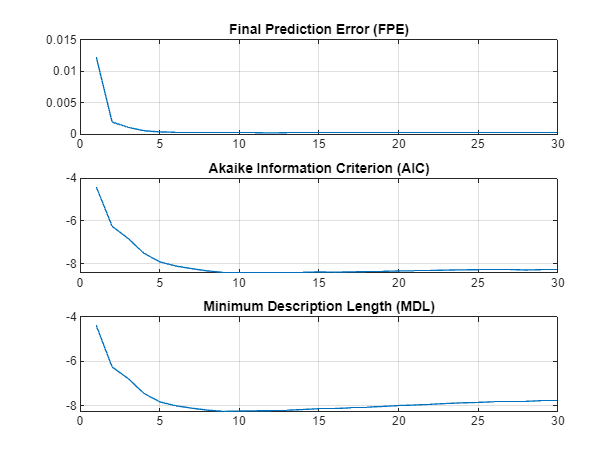

% Plotting surrogate indexes
figure(14),

% Final Prediction Error
subplot(3,1,1), plot(1:nmax,Jfpe),
title("Final Prediction Error (FPE)"), grid

% Akaike Information Criterion
subplot(3,1,2), plot(1:nmax,Jaic),
title("Akaike Information Criterion (AIC)"), grid

% Minimum Description Length
subplot(3,1,3), plot(1:nmax,Jmdl),
title("Minimum Description Length (MDL)"), grid;

As we can see they initially decrease when increasing the order of the model and then increase. Now it is better shown the behaviour of these indexes to penalize very large values of the order of the model, at the point that they weight more than the adherence.

The Minimum Description Length (MDL) index is the most valuable index because it shows clearly which is the optimal order.

% Optimal order
nopt = find(Jmdl == min(Jmdl))

nopt = 9

This optimal order is equal to the one found with the adherence indexes in the previous case. 

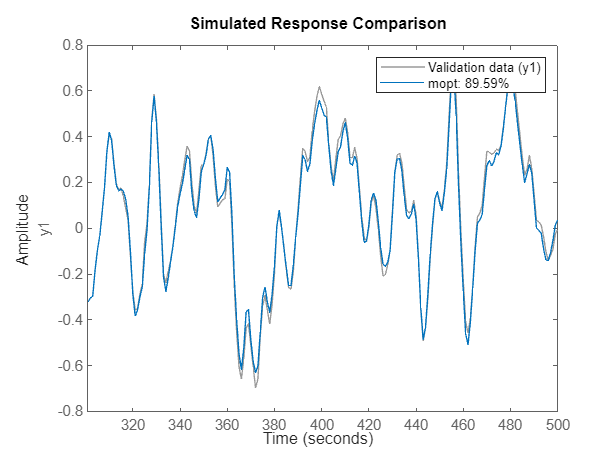

% Optimal model
mopt = arx(data(1:Ns),[nopt,nopt,1]);

% Evaluating model
figure(15), compare(data(Ns+1:500),mopt)

As we can see, this model is better than the one found with prediction adherence indexes but worse than the one found with simulation adherence indexes. This means that Minimum Description Length is a good criterion to rely on.

### 4.4. Considering heavy uncertainty

Let's now consider the dataset `data4` which represents the case where there is a heavy uncertainty in the system.

data = data4;

We now suppose that we only have 300 samples, so we cannot perform the split of the dataset.

% Number of samples
Ns = 300;

Since we want to assess the behaviour of the surrogate index with respect to the order of the model chosen for identification, we will use a `for` loop to iterate over the possible values of the order. For this reason, we define a maximum order in order to stop the loop.

% Maximum order
nmax = 30;

for k=1:nmax

Once the loop has stated, we identify the system using an ARX model.

    % ARX(k,k,1) model
    m = arx(data(1:Ns),[k,k,1]);

Then we simulate the model in order to compute the simulated output. We also consider the real output.

    % Real output
    y = data.y;

    % Simulated output
    ys = sim(m,data.U);

In this way we can compute the simulation error as their difference. We also evaluate the prediction error using the command `pe`.

    % Simulation error
    es = y - ys;
    ep = pe(m,data).OutputData;

Given the prediction error and the simulation error, we can compute the adherence indexes.

    % Adherence indexes based on the prediction error
    JP(k) = cov(ep(1:Ns));

    % Adherence indexes based on the simulation error
    JS(k) = cov(es(1:Ns));

Given the adherence indexes we can compute the surrogate indexes.

    % Final Prediction Error
    Jfpe(k) = fpe(m);

    % Akaike Information Criterion
    Jaic(k) = aic(m);

    % Minimum Description Length
    Jmdl(k) = log(Ns)*2*k/Ns + log(JP(k));

end

Now we can plot the surrogate indexes in order to evaluate them.

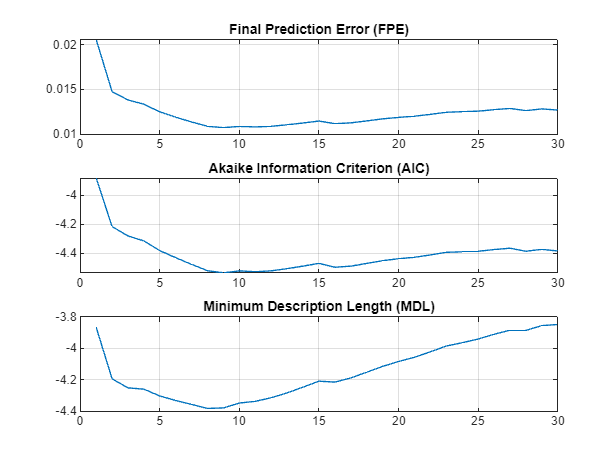

% Plotting surrogate indexes
figure(16),

% Final Prediction Error
subplot(3,1,1), plot(1:nmax,Jfpe),
title("Final Prediction Error (FPE)"), grid

% Akaike Information Criterion
subplot(3,1,2), plot(1:nmax,Jaic),
title("Akaike Information Criterion (AIC)"), grid

% Minimum Description Length
subplot(3,1,3), plot(1:nmax,Jmdl),
title("Minimum Description Length (MDL)"), grid;

As we can see they initially decrease when increasing the order of the model and then increase. Now it is better shown the behaviour of these indexes to penalize very large values of the order of the model, at the point that they weight more than the adherence.

The Minimum Description Length (MDL) index is the most valuable index because it shows clearly which is the optimal order.

% Optimal order
nopt = find(Jmdl == min(Jmdl))

nopt = 8

This optimal order is equal to the one found with the adherence indexes in the previous case. 

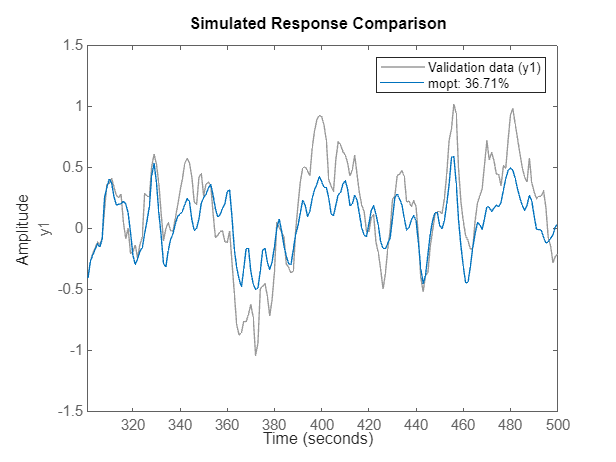

% Optimal model
mopt = arx(data(1:Ns),[nopt,nopt,1]);

% Evaluating model
figure(17), compare(data(Ns+1:500),mopt)

As we can see, this model is the same that we previously found with the simulation adherence indexes.